#### Manoli Philip Tramountanas

#### AMATH 301 A - Autumn 2020

#### November 6, 2020

# **Homework 4 Solutions**

## **Problem 1**

% Define anonymous fxn
fxy = @(x,y) exp(-0.2).*sqrt(x.^2 + y.^2) + 3.*(cos(2.*x) + sin(2.*y));
f = @(p) fxy(p(1), p(2));

% Create x & y domains
x = linspace(-3, 3, 40);
y = linspace(-3, 3, 40);
[X, Y] = meshgrid(x, y);

set(gca, 'Fontsize', 15);

a) Create a surface plot of the Modified Ackley Function.

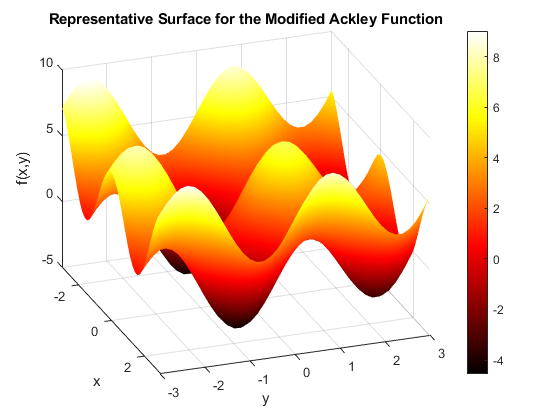

figure(1);
surf(X, Y, fxy(X, Y));
colormap('hot');
colorbar;
view(70,30);
shading interp;
xlabel('x');
ylabel('y');
zlabel('f(x,y)');
title('Representative Surface for the Modified Ackley Function');

b) Create a contour plot of the Modified Ackley Function.

figure(2);
x = linspace(-3, 3, 100);
y = linspace(-3, 3, 100);
[X, Y] = meshgrid(x, y);
contourf(X, Y, fxy(X, Y));
colormap('jet');
xlabel('x');
ylabel('y');
colorbar;
title('Ackley Function Contour Grid with Relevant Data Points');

c) Add appropriate contour markers.

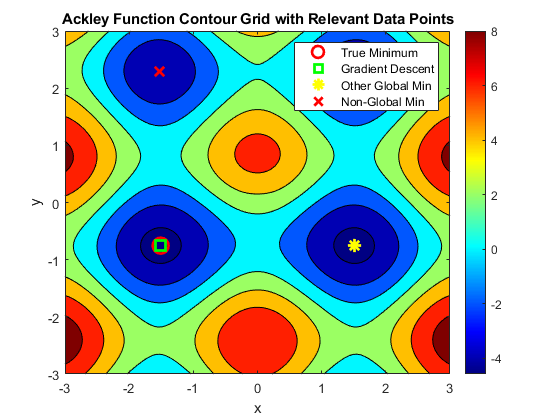

% Add markers for solutions from coding problem #2
load('writeup_data.mat');
hold on;
point1 = plot(fmsARGMIN(1), fmsARGMIN(2), 'ro',...
    'DisplayName', 'True Minimum',...
    'MarkerSize', 12,...
    'Linewidth', 2);
point2 = plot(gradARGMIN(1), gradARGMIN(2), 'gs',...
    'DisplayName', 'Gradient Descent',...
    'MarkerSize', 10,...
    'Linewidth', 2);

% Find & add marker for other global minimum
argmin_g2 = fminsearch(f, [1 -1]'); % Initial guess: (x, y) = (1, -1)
point3 = plot(argmin_g2(1), argmin_g2(2), 'y*',...
    'DisplayName', 'Other Global Min',...
    'MarkerSize', 10,...
    'Linewidth', 2);

% Find & add marker for a non-global minimum
argmin_loc = fminsearch(f, [-1 0.9]'); % Initial guess: (x, y) = (-1, 0.9)
point4 = plot(argmin_loc(1), argmin_loc(2), 'rx',...
    'DisplayName', 'Non-Global Min',...
    'MarkerSize', 10,...
    'Linewidth', 2);

% Create a legend for all markers
legend( [point1, point2, point3, point4] );

## Problem 2

% Define Table Values
Method =...
    ["tstep = 0.01"
    "tstep = 0.1"
    "tstep = 0.15"
    "tstep = 0.2"
    "fminbound"];
NumberOfIterations = [0; 0; 0; 0; 0];
Time = [0;0;0;0;0];
Converged = ["";"";"";"";""];

% Define Generic Algorithm Values
p0 = [-1 -0.5]';
tol = 1e-10;
maxItr = 10000;
gradfxy = @(x,y)...
    [exp(-0.2).*(x./sqrt((x.^2)+(y.^2))) - 6.*sin(2.*x)
    exp(-0.2).*(y./sqrt((x.^2)+(y.^2))) + 6.*cos(2.*y)];
gradf = @(p) gradfxy(p(1), p(2));

a) Find time and number of iterations to complete gradient descent with fminbnd.

p = p0;
tic
grad = gradf(p0);
while (norm(grad, inf) > tol && NumberOfIterations(5) < maxItr)
    phi = @(t) p - t*grad;
    f_of_phi = @(t) f(phi(t));
    p = phi(fminbnd(f_of_phi, 0, 1));
    NumberOfIterations(5) = NumberOfIterations(5) + 1;
    grad = gradf(p);
end
Time(5) = toc;

if (NumberOfIterations(5) < maxItr)
    Converged(5) = "Y";
else
    Converged(5) = "N";
end

b) Find time and number of iterations to complete gradient descent with tstep = 0.01.

tstep = 0.01;
p = p0;
tic
grad = gradf(p0);
while (norm(grad, inf) > tol && NumberOfIterations(1) < maxItr)
    p = p - tstep*grad;
    grad = gradf(p);
    NumberOfIterations(1) = NumberOfIterations(1) + 1;
end
Time(1) = toc;

if (NumberOfIterations(1) < maxItr)
    Converged(1) = "Y";
else
    Converged(1) = "N";
end

c) Repeat part (b) with tstep = 0.1.

tstep = 0.1;
p = p0;
tic
grad = gradf(p0);
while (norm(grad, inf) > tol && NumberOfIterations(2) < maxItr)
    p = p - tstep*grad;
    grad = gradf(p);
    NumberOfIterations(2) = NumberOfIterations(2) + 1;
end
Time(2) = toc;

if (NumberOfIterations(2) < maxItr)
    Converged(2) = "Y";
else
    Converged(2) = "N";
end

d) Repeat part (b) with tstep = 0.15.

tstep = 0.15;
p = p0;
tic
grad = gradf(p0);
while (norm(grad, inf) > tol && NumberOfIterations(3) < maxItr)
    p = p - tstep*grad;
    grad = gradf(p);
    NumberOfIterations(3) = NumberOfIterations(3) + 1;
end
Time(3) = toc;

if (NumberOfIterations(3) < maxItr)
    Converged(3) = "Y";
else
    Converged(3) = "N";
end

e) Repeat part (b) with tstep = 0.2.

tstep = 0.2;
p = p0;
tic
grad = gradf(p0);
while (norm(grad, inf) > tol && NumberOfIterations(4) < maxItr)
    p = p - tstep*grad;
    grad = gradf(p);
    NumberOfIterations(4) = NumberOfIterations(4) + 1;
end
Time(4) = toc;

if (NumberOfIterations(4) < maxItr)
    Converged(4) = "Y";
else
    Converged(4) = "N";
end

f) Record results in a table.

T = table(Method, NumberOfIterations, Time, Converged);
disp(T);

        Method        NumberOfIterations      Time       Converged
    ______________    __________________    _________    _________

    "tstep = 0.01"            198           0.0060099       "Y"   
    "tstep = 0.1"              17           0.0049706       "Y"   
    "tstep = 0.15"            162            0.005641       "Y"   
    "tstep = 0.2"           10000           0.0092519       "N"   
    "fminbound"              1300             0.20518       "Y"   



Note for the table: "Time" is measured in seconds.

g) Comment on the results in the table.

The gradient descent method did not always converge when finding the minimum, as seen by the results for tstep = 0.2. It did not converge for this value of tstep because the algorithm reached a point where the current guess passed over ${\mathrm{argmin}}_p f\left(p\right)$, and the relatively large magnitude of tstep caused the algorithm to oscillate between two values of p  not at the minimum rather than converging onto ${\mathrm{argmin}}_p f\left(p\right)$. The algorithm converged fastest when using the tstep code for tstep = 0.1, and it converged in the fewest number of iterations when using the tstep code for tstep = 0.1. The answer to these questions is the same in this case because the code block for each iteration for the two fastest algorithms is the same, meaning that fewer iterations generally lends itself to a faster solve speed. However, it could potentially be different if the code block for one solve requires more operations than the code block for a different solve. For example, the tstep solve for tstep = 0.2 took many more iterations to complete than the fminbound solve, but because the fminbound solve takes more operations per iteration than the tstep solve, it was still slower than the tstep solve.